%Here is a random generator, We used these random seeds
rng(20, "multFibonacci");
%14, 15, 18, 20
%Here we can specify the number, how it should be saved
g = 4;

%Here we create the basic 20*20 map
mapWidth = 20;
mapLength = 20;
Map = ones(mapLength, mapWidth);

%In order for it to work properly with every path planning algorithm, we
%have to give it 1 meter wide frame
Map(2:end-1, 2:end-1) = 0;
omap = occupancyMap(Map);



%We have to specify the number of obstacles in the space, here we create 5
numberofObs = 0;
RequiredObs = 5;

%We have to repeat it until it reaches the required obstacle number
while RequiredObs ~= numberofObs

  %This generates random numbers between 1 and 4. Which gives us back a
  %scalar number (1, dictates that it creates a 1 by 1 vector, but if we write
  %2 it would create a 2 by 2 matrix, or we can specify what size of matrix
  %we want, like randi([-5, 5], 10, 1). This would determine how big is our
  %obstacle
    width = randi([1 4], 1);
    length = randi([1 4], 1);

  %This gives the starting x and y coordinates to the obstacle. We have to subtract the width and the length if we do not want to go over the map

    
    xPosition = randi([1 mapWidth - width], 1);
    yPosition = randi([1 mapLength - length], 1);

    %Meshgrid returns a gridmap with the obstacles
    [xobstacle, yobstacle] = meshgrid(xPosition:xPosition+width, yPosition:yPosition+length);
    xyzObs = [xobstacle(:) yobstacle(:)];

    %Here we are going to check if the new obstacle overlaps with any other
    %obstacles. If not, it will update the occupancy map with the created
    %obstacles coordinates.
    checkIntersection =false;
    for i = 1:size(xyzObs, 1)
        if checkOccupancy(omap, xyzObs(i,:)) == 1
            checkIntersection = true;
            break
        end
    end

    if ~checkIntersection
        for i = 1:size(xyzObs,1)
            Map(xyzObs(i,2), xyzObs(i,1)) = 1;
        end
        setOccupancy(omap, xyzObs, 1);
        numberofObs = numberofObs+1;
    end
end



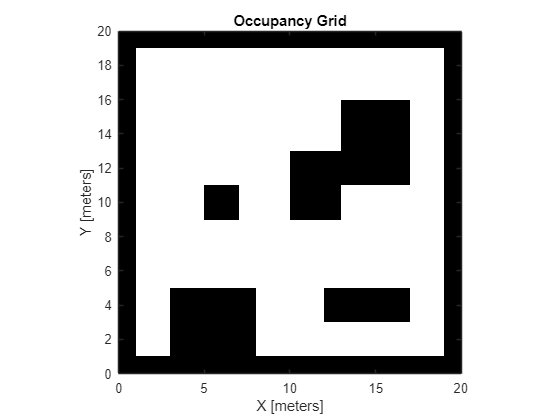

%Here we are going to look at our map
show(omap)

%We are going to save the map, with the corresponding number, into the
%specified folder. We have to save the Occupancy map object and the Matrix,
%which was the base of the Occupancy map

save("2D\occupancy_map" + g + ".mat", "omap");
save("2D\occupancy_map_data"+g+".mat", "Map")
